# Average Population Velocity vs. Turning Frequency

by Ercag June 2021 

clearvars;
close all;

## Define Export Path for figures

ExpPath = 'C:\Users\ercagp\Box\Research\VibrioFischeri_Project\Data\RunReverseAnalysis\EventRates';

## Call the run reverse analysis files

MainPath = 'C:\Users\ercagp\Documents\Rowland_Data\RunReverseAnalysis\RunReverse_Data';
GenExpPath = MainPath; 
StrainLabels = {'KMT47'};

## Input parameters

%Acquisition and ADMM parameter
fps = 30; %Hz
Lambda = 0.5; 

%Time stamp for the PNG/PDF files
Stamp =  ['[' char(datetime('now','Format','yyyyMMdd')) ']'];

%RegExp Keys
RegKeyROI = 'ROI[_]\d';
RegKeyVD = ['(?<=Data' filesep ')\d*'];


%IPTG vector for the plot 
IPTG_X = [0, 25, 35, 50, 60, 75, 100,1000]; 

%Plot parameters 
PP.Lab.XAx = 'Mean Speed per Acq.(\mum/sec)'; 
PP.Lab.YAx = 'Turn Frequency (sec^{-1})';
% PP.Lim.X  = [40 140]; 
% PP.Lim.Y  = [0.5 1.5]; 
ColorMap = linspecer(length(StrainLabels),'qualitative'); 
ColorMap_IPTG = linspecer(length(IPTG_X),'qualitative');

## Calculate Turn Frequency & Mean Speed

    Files = callResultsv2(MainPath, StrainLabels{1},Lambda);    
    %Find ROIs and Video dates
    VideoDates = regexp(Files,RegKeyVD,'match','once');
    ROI = regexp(Files,RegKeyROI,'match','once');
    
    %Preallocate
    IPTG = zeros(length(Files),1);
    TurnSum = zeros(length(Files),1);
    TrajDur = zeros(length(Files),1);
    TurnFreq = cell(length(Files),2);
    AllSpeeds = cell(length(Files),1);
    MeanSpeeds_perAcq = cell(length(Files),2);
    pH = cell(length(IPTG_X),1); 
    
    
for i = 1:length(Files) 
        load(Files{i})
        fprintf(['minimum T =' num2str(Results.minT) 'sec \n'])
        fprintf(['minimum V =' num2str(Results.minV) 'um/sec \n \n'])
        fprintf(['[IPTG] = ' num2str(RunReverse.Info.IPTG) 'uM \n \n'])
        
        IPTG(i) = RunReverse.Info.IPTG; 
        if IPTG(i) == 1
           IPTG(i) = IPTG(i)*1000; %1000uM
        end
      
        TurnSum(i) = RunReverse.TotalTurns;
        %Plot title
        MeanSpeeds_perAcq{i,1} = IPTG(i); 
        TurnFreq{i,1} = IPTG(i);

        FltMask =  filterout(Speeds,Results.minT,Results.minV,fps);
        SpeedSubset = Speeds(FltMask); 
                                                                      
        TrajDur(i) = sum(cellfun(@(x) size(x(:,1),1)./fps,SpeedSubset)); 
        AllSpeeds{i} = cell2mat(cellfun(@(x) x(:,9), SpeedSubset, 'UniformOutput', false));
        MeanSpeeds_perAcq{i,2} = mean(AllSpeeds{i},'omitnan'); 
        TurnFreq{i,2} = TurnSum(i)/TrajDur(i);
                  
         %if strcmp(VideoDates{i},'20210624')
             %Purple = [0.29,0.078,0.52]; 
             %plot(MeanSpeeds_perAcq(i),TurnFreq(i),'x','MarkerSize',12,'Color',Purple,'LineWidth',2.5);
                   
         %else
              %unique [IPTG] index

              %pH{IP} = plot(MeanSpeeds_perAcq(i),TurnFreq(i),'o','MarkerSize',9,'Color',ColorMap_IPTG(IP,:),'LineWidth',1.5);
                     
         %end
                  

end       

minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


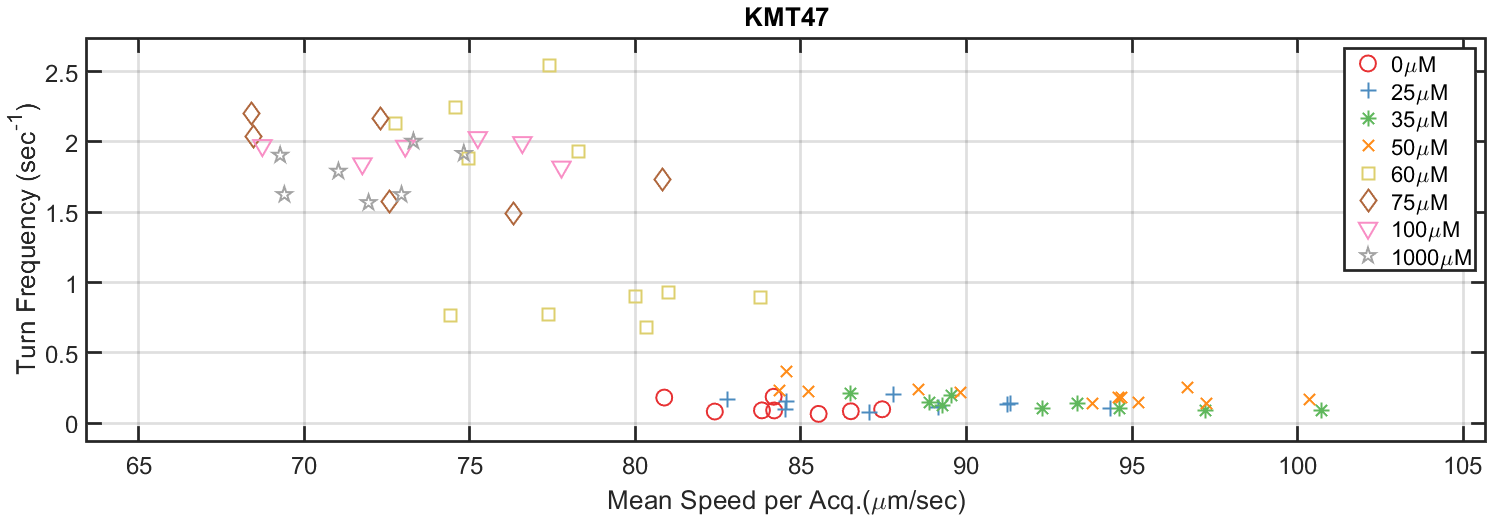

%Marker library
Markers = {'o','+','*','x','s','d','v','p'}; 
%Set the plot limits
Epsilon_X = 5; %um/sec
Epsilon_Y = 0.2; 

PP.Lim.X(1) = min([MeanSpeeds_perAcq{:,2}]) - Epsilon_X; 
PP.Lim.X(2) = max([MeanSpeeds_perAcq{:,2}]) + Epsilon_X; 

PP.Lim.Y(1) = min([TurnFreq{:,2}]) - Epsilon_Y; 
PP.Lim.Y(2) = max([TurnFreq{:,2}]) + Epsilon_Y; 


            
hf = figure; 
for k = 1:length(IPTG_X) 
    LogMask = IPTG == IPTG_X(k);
    p{k} = plot([MeanSpeeds_perAcq{LogMask,2}],[TurnFreq{LogMask,2}],Markers{k},'MarkerSize',12,'Color',ColorMap_IPTG(k,:),'LineWidth',1.5);
    PP.Lab.Title = {StrainLabels{1}}; 
    PlotSty(hf,PP.Lab,PP.Lim);
            
    hold on 
end
ax = gca; 
SetFigLarge(hf,ax)
                    
            
for l = 1:length(IPTG_X)
    IPTG_Leg{l} = [num2str(IPTG_X(l)) '\muM'];
end
                
legend([p{1:end}], IPTG_Leg);

## Functions

function [FilterMask] = filterout(S,minT,minV,fps)

         %Filter out trajectories
         TotalTime = cellfun(@(x) length(x(:,1)).*1/fps,S); 
         medV = cellfun(@(x) medianN(x(:,9)), S);
        
         FilterMask = medV > minV & TotalTime > minT;
         %SSubset = S(FilterMask); 
end

function ExportFig(hf,Strings)
                                                        
          
        if strcmp(Strings.ExpType,'PerAcq')
           FinalExpPath = fullfile(Strings.ExpPath,Strings.SubDir,Strings.PlotY,Strings.Strain,[Strings.IPTG 'uM']);
           FullFileName = [Strings.Stamp Strings.Strain '_' Strings.PlotY '_' Strings.VD '_IPTG_' Strings.IPTG 'uM_' Strings.ROI];
        else
           FinalExpPath = fullfile(Strings.ExpPath,Strings.SubDir);
           FullFileName = [Strings.Stamp Strings.PlotY];
        end
        
        if ~exist(FinalExpPath,'dir')
            mkdir(FinalExpPath)
        end   
        printfig(hf,fullfile(FinalExpPath,FullFileName),'-dpng');
        printfig(hf,fullfile(FinalExpPath,FullFileName),'-dpdf');
        savefig(hf,fullfile(FinalExpPath,FullFileName));
end

 function R = matchrepeat(X,Y)
          UX = unique(X,'stable');
          R = cell(length(UX),2);
          for i = 1:length(UX)
              Mask = X == UX(i);
              R{i,1} = unique(X(Mask));
              R{i,2} = Y(Mask);             
          end         
 end


 function [TF_MeanV, MeanV, X] = TurnFreq_MeanV(S,T,Edges,fps)
          %Find mean speed per bug 
          V = cellfun(@(x) nanmean(x(:,9)), S); 
          [N,Edge,Bins] = histcounts(V,Edges);
          for i = 1:length(Edge)-1
              Mask = Bins == i; 
              TSubset = T(Mask,:);             
              TrajDur(i) = sum(cellfun(@(x) size(x,1)./fps, TSubset(:,1))); 
              TurnSum(i) = sum(cellfun(@(x) length(x), TSubset(:,3))); 
              
              TF_MeanV(i) = TurnSum(i)/TrajDur(i); 
          end
          MeanV = Edge;
          k = 1; 
          for j = 1:length(Edge)-1
              X(k) = mean([Edge(j), Edge(j+1)]); 
              k = k + 1; 
          end
 
 end
 

 function SetFigLarge(hFig,ax)
          hFig.Color = [1 1 1];
          hFig.InnerPosition = [328,741,1472,427];
          hFig.OuterPosition = [320,733,1488,520];
          settightplot(ax); 
          hFig.PaperUnits = 'centimeters';
          hFig.PaperPosition = [1 2.0 28 16.8];
 end
 
function PlotSty(hFig,Lab,Lim)
         figure(hFig);
         ax = gca; 
         ax.Title.String = Lab.Title;
         ax.XLabel.String = Lab.XAx; 
         ax.YLabel.String = Lab.YAx;
         ax.XLim = Lim.X;
         ax.YLim = Lim.Y; 
         ax.XScale = 'lin';
         ax.FontSize = 18;
         ax.FontName =  'Helvetica';
         ax.LineWidth = 2.0; 
         ax.Box = 'on';
         grid on
%ErcagGraphics
         %SetFigLarge(hFig,ax)
end